Step 1: Load Dataset

data = readtable("C:\Users\yashw_d6scpoj\Desktop\MFCEOC\smoted_dataset.csv");

Step 2: Remove Non-Numeric Features (src_ip, dst_ip)

data(:, {'src_ip', 'dst_ip'}) = []; % Remove categorical columns

Step 3: Extract Features and Target Variable

X = table2array(data(:, 1:end-1)); % Convert numeric features to matrix
Y = table2array(data(:, end)); % Convert labels to numeric array

% Convert categorical labels to numerical if needed
Y = grp2idx(Y);


Step 4: Split data into training (80%) and testing (20%)

cv = cvpartition(Y, 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);

Training and Prediction

% Train Random Forest model
numTrees = 100; % Number of trees
RF_model = TreeBagger(numTrees, X_train, Y_train, 'Method', 'classification');

% Predict on test data
RF_pred = str2double(predict(RF_model, X_test));

Evaluation

% Calculate Accuracy
RF_accuracy = sum(RF_pred == Y_test) / length(Y_test) * 100;
disp(['Random Forest Accuracy: ', num2str(RF_accuracy), '%'])

Random Forest Accuracy: 99.9764%


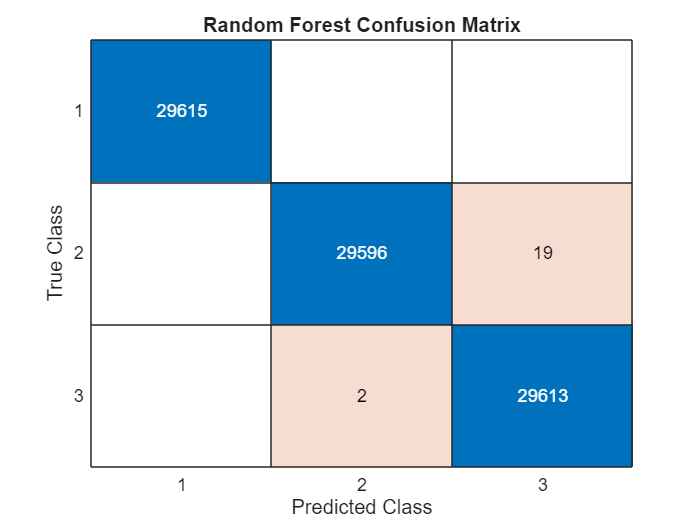


% Confusion Matrix
figure;
confusionchart(Y_test, RF_pred);
title('Random Forest Confusion Matrix');